blockOption:0	slice_height:1
H.261 quantization	quant_factor=50
two symbol coding
input image bit:131072


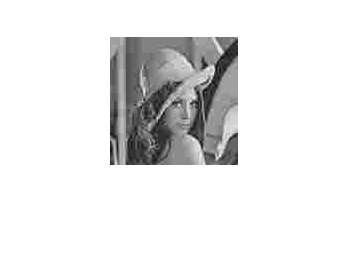

Processed image bit:20389
Quantization success!
huffmanSymbols.len = 5
escape_prob_threshold = 0.900000
Two symbol encode: 	Slice_height:128
Two symbol encode:	Encode success!	 Total bits:135668
Two symbol decode:	slice_idx:0


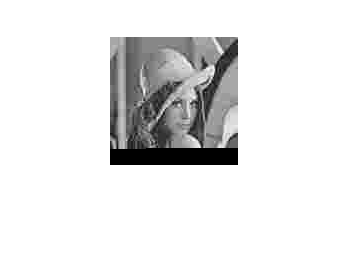

Two symbol decode:\tReconstruction failed!
save the processed image correctly.
save the reconstructed image correctly.


blockOption:1	slice_height:4
H.261 quantization	quant_factor=50
two symbol coding
input image bit:131072


Processed image bit:20389
Quantization success!
huffmanSymbols.len = 5
escape_prob_threshold = 0.900000
Two symbol encode: 	Slice_height:4
Two symbol encode:	Encode success!	 Total bits:136660
Two symbol decode:	slice_idx:0
Two symbol decode:	slice_idx:1
Two symbol decode:	slice_idx:2
Two symbol decode:	slice_idx:3
Two symbol decode:	slice_idx:4
Two symbol decode:	slice_idx:5
Two symbol decode:	slice_idx:6
Two symbol decode:	slice_idx:7
Two symbol decode:	slice_idx:8
Two symbol decode:	slice_idx:9
Two symbol decode:	slice_idx:10
Two symbol decode:	slice_idx:11
Two symbol decode:	slice_idx:12
Two symbol decode:	slice_idx:13
Two symbol decode:	slice_idx:14
Two symbol decode:	slice_idx:15
Two symbol decode:	slice_idx:16
Two symbol decode:	slice_idx:17
Two symbol decode:	slice_idx:18
Two symbol decode:	slice_idx:19
Two symbol decode:	slice_idx:20
Two symbol decode:	slice_idx:21
Two symbol decode:	slice_idx:22
Two symbol decode:	slice_idx:23
Two symbol decode:	slice_idx:24
Two symbol decode

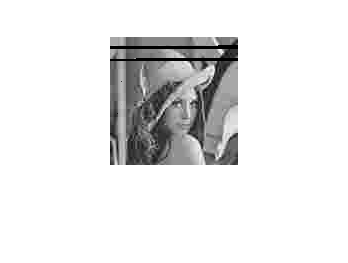

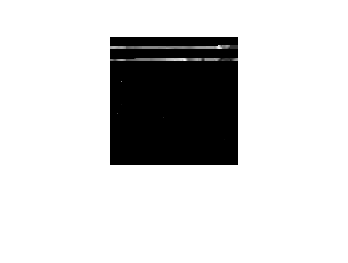

PSNR:	 difference between picture A and B.
Two symbol decode:	Reconstruction success but not match!
PSNR:18.047335
save the processed image correctly.
save the reconstructed image correctly.


blockOption:2	slice_height:8
H.261 quantization	quant_factor=50
two symbol coding
input image bit:131072


Processed image bit:20389
Quantization success!
huffmanSymbols.len = 5
escape_prob_threshold = 0.900000
Two symbol encode: 	Slice_height:8
Two symbol encode:	Encode success!	 Total bits:136148
Two symbol decode:	slice_idx:0
Two symbol decode:	slice_idx:1
Two symbol decode:	slice_idx:2
Two symbol decode:	slice_idx:3
Two symbol decode:	slice_idx:4
Two symbol decode:	slice_idx:5
Two symbol decode:	slice_idx:6
Two symbol decode:	slice_idx:7
Two symbol decode:	slice_idx:8
Two symbol decode:	slice_idx:9
Two symbol decode:	slice_idx:10
Two symbol decode:	slice_idx:11
Two symbol decode:	slice_idx:12
Two symbol decode:	slice_idx:13
Two symbol decode:	slice_idx:14
Two symbol decode:	slice_idx:15


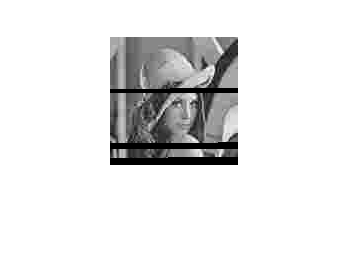

Two symbol decode:\tReconstruction failed!
save the processed image correctly.
save the reconstructed image correctly.


blockOption:3	slice_height:16
H.261 quantization	quant_factor=50
two symbol coding
input image bit:131072


Processed image bit:20389
Quantization success!
huffmanSymbols.len = 5
escape_prob_threshold = 0.900000
Two symbol encode: 	Slice_height:16
Two symbol encode:	Encode success!	 Total bits:135892
Two symbol decode:	slice_idx:0
Two symbol decode:	slice_idx:1
Two symbol decode:	slice_idx:2
Two symbol decode:	slice_idx:3
Two symbol decode:	slice_idx:4
Two symbol decode:	slice_idx:5
Two symbol decode:	slice_idx:6
Two symbol decode:	slice_idx:7


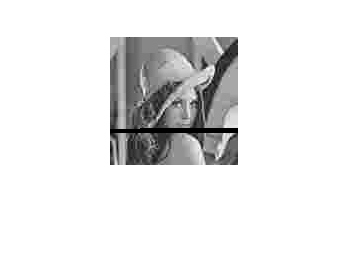

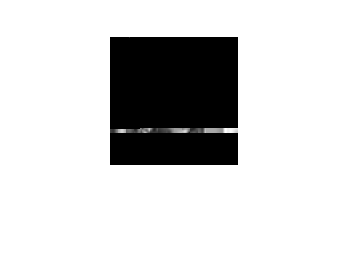

PSNR:	 difference between picture A and B.
Two symbol decode:	Reconstruction success but not match!
PSNR:19.096265
save the processed image correctly.
save the reconstructed image correctly.


blockOption:4	slice_height:32
H.261 quantization	quant_factor=50
two symbol coding
input image bit:131072


Processed image bit:20389
Quantization success!
huffmanSymbols.len = 5
escape_prob_threshold = 0.900000
Two symbol encode: 	Slice_height:32
Two symbol encode:	Encode success!	 Total bits:135764
Two symbol decode:	slice_idx:0
Two symbol decode:	slice_idx:1
Two symbol decode:	slice_idx:2
Two symbol decode:	slice_idx:3


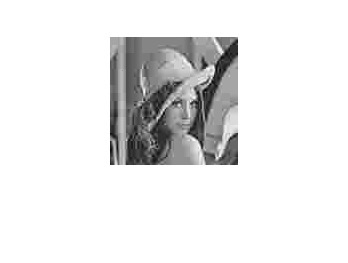

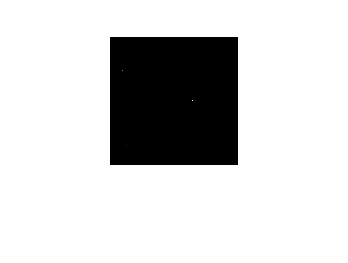

PSNR:	 difference between picture A and B.
Two symbol decode:	Reconstruction success but not match!
PSNR:24.996983
save the processed image correctly.
save the reconstructed image correctly.


blockOption:5	slice_height:64
H.261 quantization	quant_factor=50
two symbol coding
input image bit:131072


Processed image bit:20389
Quantization success!
huffmanSymbols.len = 5
escape_prob_threshold = 0.900000
Two symbol encode: 	Slice_height:64
Two symbol encode:	Encode success!	 Total bits:135700
Two symbol decode:	slice_idx:0
Two symbol decode:	slice_idx:1


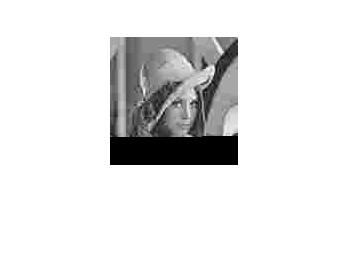

Two symbol decode:\tReconstruction failed!
save the processed image correctly.
save the reconstructed image correctly.


PSNRs = zeros(10, 6);
SNR = 10;
quant_factor = 50;
for index_PSNRs = 1:1
    for blockOption = 0:5
        codec
        PSNRs(index_PSNRs, blockOption+1) = PSNR(srcImage, recImage);
        disp("========")
    end
end

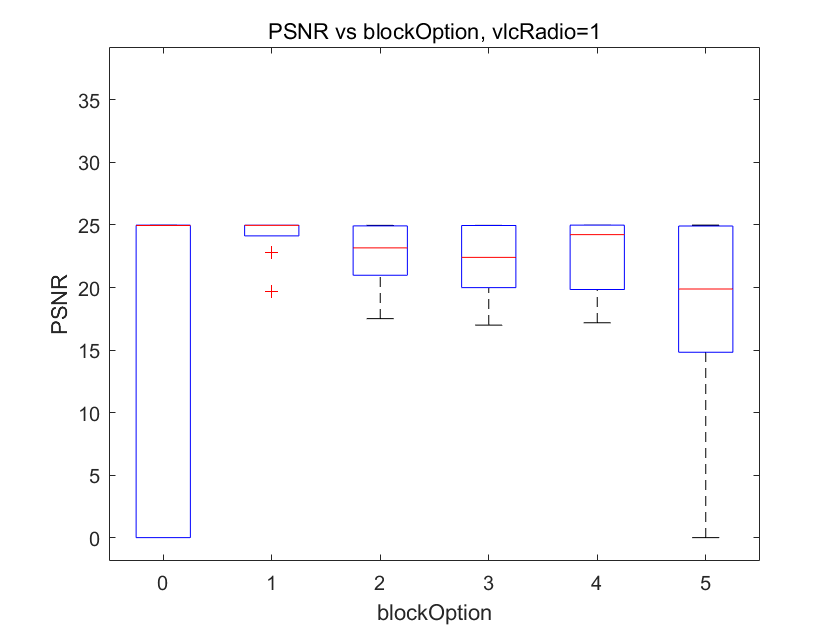

boxplot(PSNRs)
xticklabels(string(0:5))
xlabel("blockOption")
ylabel("PSNR")
title("PSNR vs blockOption, vlcRadio=1")
imwrite(frame2im(getframe(gcf)), "双符号boxplt.png")

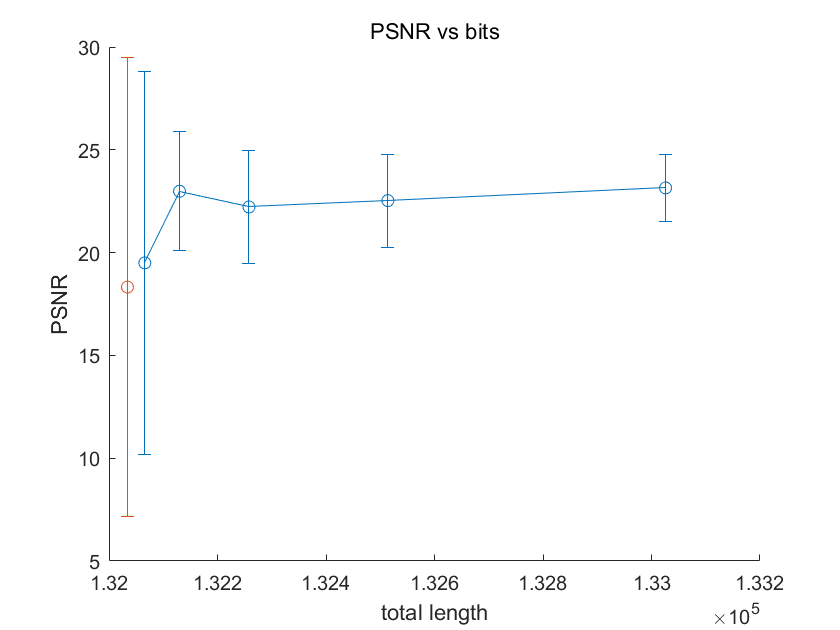

figure; hold on;
l0 = [132034
133026
132514
132258
132130
132066];
P0 = [13.9569   24.3526   16.9089   24.0989   20.3510   18.1902
24.9419   24.5391   21.7815   16.3806   24.1908   14.5144
14.3005   19.1929   22.3526   24.9407   20.4171   21.9345
13.4759   24.8006   17.0487   21.5211   21.9960   18.6445
12.1509   24.4583   24.6954   19.5933   23.8081   17.1479
24.9819   18.5123   22.9492   24.6781   24.9465   19.1279
24.9660   23.8074   24.9441   21.2734   24.3246   18.4067
16.4617   24.3797   24.6601   24.7310   21.6158   21.2382
19.1211   24.7020   24.9738   20.7875   23.9528   22.0440
18.8929   22.6980   24.9712   24.1766   24.2358   23.7426];
l1 = [120955
121947
121435
121179
121051
120987];
P1 = [      0   24.9837   24.9540   20.0465   24.9797   24.8715
24.9878   19.6922   24.9264   24.9663   17.1799   24.9791
17.3760   24.9916   17.5134   21.1143   18.4225   22.2085
24.9444   22.8231   20.9756   23.7110   23.4897   17.5608
      0   24.6689   24.9689   24.9567   24.9732         0
24.9689   24.9865   22.0355   24.9570   25.0006   24.9873
24.9989   24.9849   23.4180   19.7250   21.9670   15.1812
24.9946   24.9453   24.0320   24.9383   24.9835   24.9228
24.9855   24.1276   22.9249   16.9919   19.8440         0
      0   24.9904   20.8208   19.9909   24.9983   14.8279];
m0 = mean(P0, 1);
s0 = std(P0, 1);
m1 = mean(P1, 1);
s1 = std(P1, 1);
errorbar(l0(2:end), m0(2:end), s1(2:end), "o-")
errorbar(l0(1), m0(1), s1(1), 'o')
%errorbar(l1(2:end), m1(2:end), s1(2:end), "o-")
%errorbar(l1(1), m1(1), s1(1), 'o')
xlabel("total length")
ylabel("PSNR")
title("PSNR vs bits")
hold off
imwrite(frame2im(getframe(gcf)), "errorbar.png")

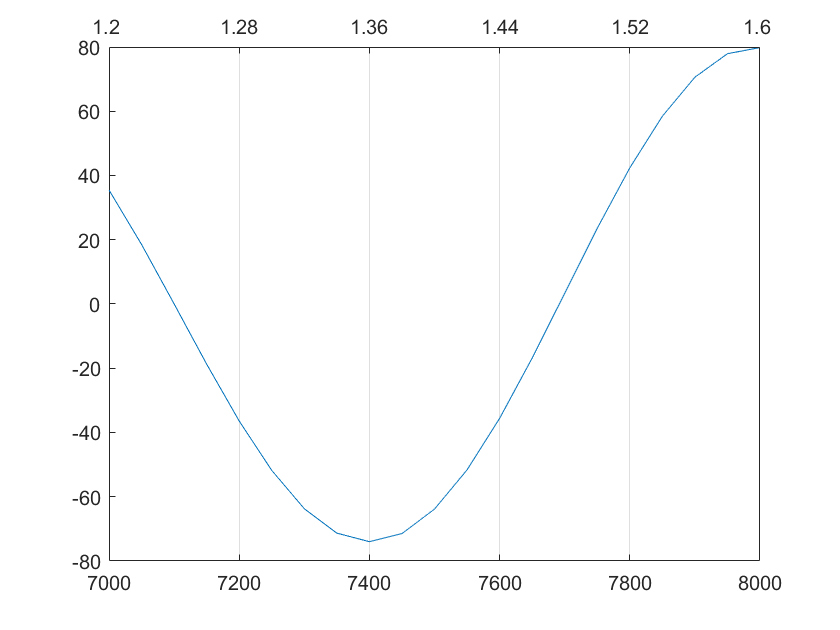

figure
ha = axes;
hb = axes(...
'Position', get(ha, 'Position'), ...
'XAxisLocation', 'top', ...
'YAxisLocation', 'right', ...
'Color', 'none');
set(hb,'YTickLabel','','YTick',[])

x=7000:50:8000;
y=x.*sin(x)./100;
plot(ha,x,y)

hbXTick=linspace(1.2,2,11);%上边XTick
set(hb,'XTickLabel',hbXTick);%上边XTick
set(ha,'box','off','xgrid','on')